# Pierwsza Metoda Lapunova

## Układ mechaniczny


$$\ddot{y}(t) + b\dot{y}(t) + cy(t) + dy^{3}(t) = 0$$


syms x1 x2 b c d
J = [0, 1; -c-3*d*x1^2, -b]

$$J = \left(\begin{array}{cc} 0 & 1\\ -3\,d\,{x_{1}}^{2}-c & -b \end{array}\right)$$

% P(0,0) lub d>0
J1 = [0 1; -c -b]

$$J1 = \left(\begin{array}{cc} 0 & 1\\ -c & -b \end{array}\right)$$

eig(J1)

$$ans = \left(\begin{array}{c} -\frac{b}{2}-\frac{\sqrt{b^{2}-4\,c}}{2}\\ \frac{\sqrt{b^{2}-4\,c}}{2}-\frac{b}{2} \end{array}\right)$$


% pozostałe 
J2 = [0 1; 2*c -b]

$$J2 = \left(\begin{array}{cc} 0 & 1\\ 2\,c & -b \end{array}\right)$$

eig(J2)

$$ans = \left(\begin{array}{c} -\frac{b}{2}-\frac{\sqrt{b^{2}+8\,c}}{2}\\ \frac{\sqrt{b^{2}+8\,c}}{2}-\frac{b}{2} \end{array}\right)$$

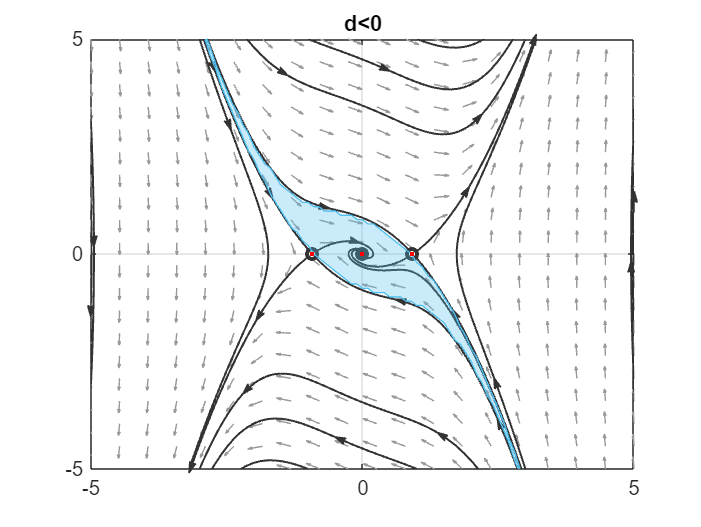

clear all
b = 0.5;
c = 0.6;
d = -0.7;

odefun = @(t, x)system31(t, x, b, c, d);
plotpp(odefun)
hold on
x_ = [];
y_ = [];

for x_1 = -10:0.1:10
    for x_2 = -10:0.1:10
        [t,y] = ode45 (@(t, x)system31(t, x, b, c, d), [0 100], [x_1 x_2] );
        if abs(y(end,1)) < 0.0001 && abs(y(end, 2)) < 0.0001 
            x_(end + 1) = x_1;
            y_(end + 1)= x_2;
        end
    end
end

arg = [];
first = [];
second = [];
for x_1 = x_
    arg(end + 1) = x_1;
    index = find(x_ == x_1);
    values = y_(index);
    first(end + 1) = min(values);
    second(end + 1) = max(values);
end

x_ = [arg,sort(arg, 'descend')];
y_ = [first, flip(second)];
p = fill (x_ ,y_ ,[0.3010 0.7450 0.9330],'FaceAlpha',0.3);
p.EdgeColor = [0.3010 0.7450 0.9330];
plot(0, 0, '.', 'Color', 'red')
plot(sqrt(-c/d), 0, '.', 'Color', 'red')
plot(-sqrt(-c/d), 0, '.', 'Color', 'red')
title('d<0')
hold off

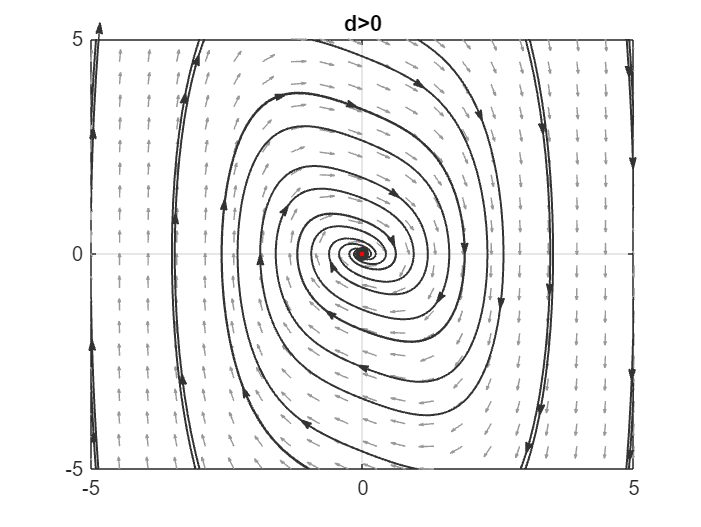

d = 0.7;

odefun = @(t, x)system31(t, x, b, c, d);
plotpp(odefun)
hold on
plot(0, 0, '.', 'Color', 'red')
title('d>0')
hold off

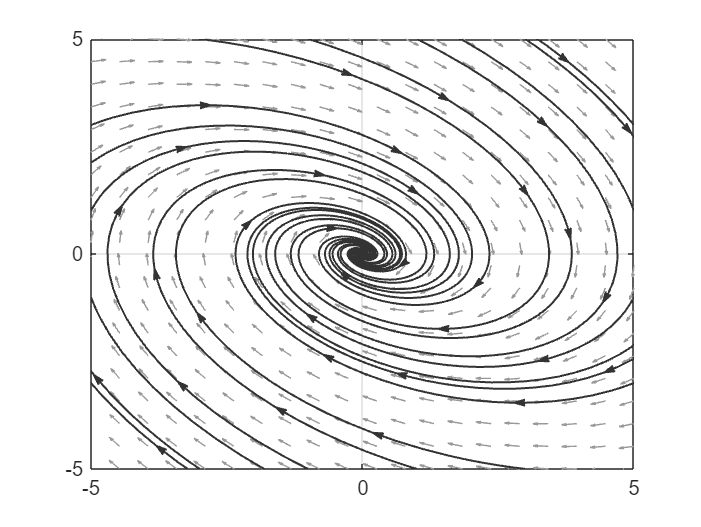

x0 = [0.1 0.1];
J = [0 1; -c -b];
plotpp(@(t, x)J*[x(1); x(2)])

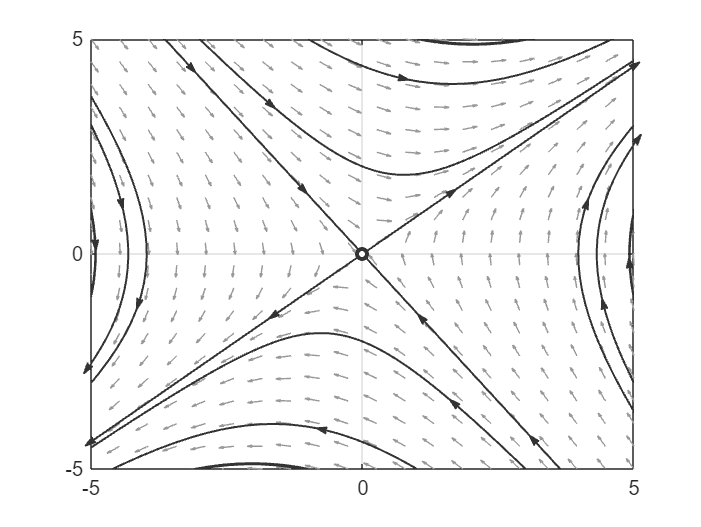

J = [0 1; 2*c -b];
plotpp(@(t, x)J*[x(1); x(2)])

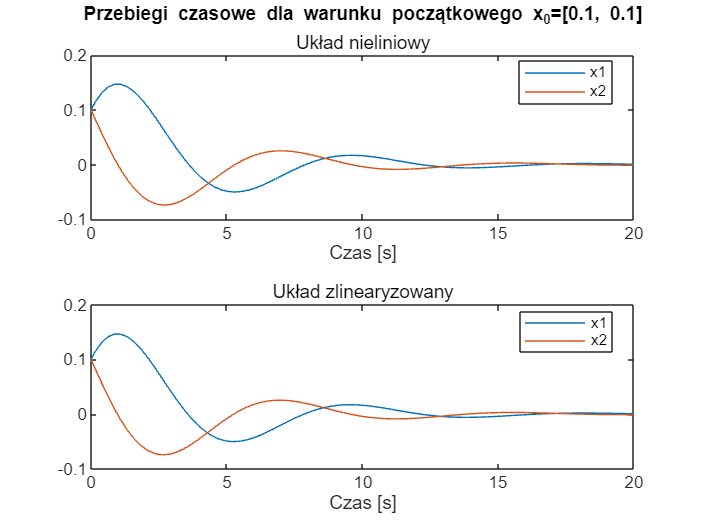

figure 
close all;
clear all;
sim_time = 20;
subplot(2,1,1)
b = 0.5;
c = 0.6;
d = -0.7;
x0=[0.1, 0.1];
[t, xx] = ode45(@(t,x) system31(t,x,b,c,d), [0 sim_time], x0);
plot(t,xx)
title(sprintf('Przebiegi czasowe dla warunku początkowego x_0=[%g, %g]', x0(1), x0(2)))
subtitle('Układ nieliniowy')
xlabel("Czas [s]")
legend("x1","x2","Location","best")

subplot(2,1,2)
x=[0,0];
A=[0, 1; -3*d*x(1)^2-c, -b];
[t1, xx1] = ode45(@(t,x) A*[x(1);x(2)], [0 sim_time], x0);
plot(t1,xx1)
subtitle('Układ zlinearyzowany')
xlabel("Czas [s]")
legend("x1","x2","Location","best")
saveas(gcf,'przebiegi1.png')

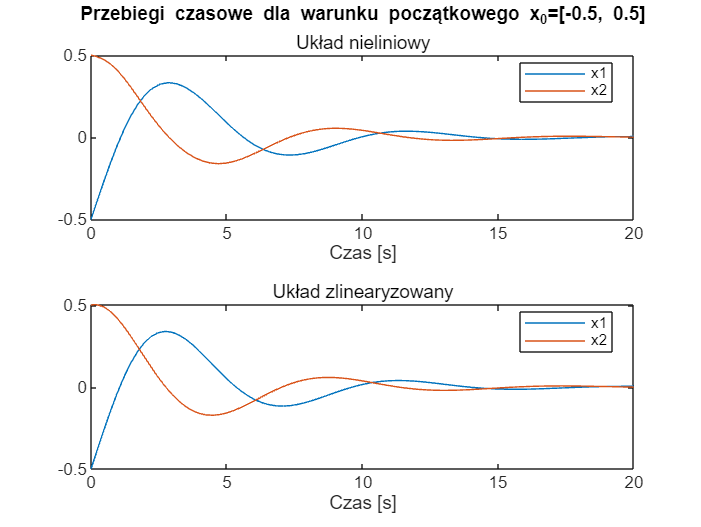

figure 
close all;
clear all;
subplot(2,1,1)
sim_time = 20;
b = 0.5;
c = 0.6;
d = -0.7;
x0=[-0.5, 0.5];
[t, xx] = ode45(@(t,x) system31(t,x,b,c,d), [0 sim_time], x0);
plot(t,xx)
title(sprintf('Przebiegi czasowe dla warunku początkowego x_0=[%g, %g]', x0(1), x0(2)))
subtitle('Układ nieliniowy')
xlabel("Czas [s]")
legend("x1","x2","Location","best")

subplot(2,1,2)
x=[0,0];
A=[0, 1; -3*d*x(1)^2-c, -b];
[t1, xx1] = ode45(@(t,x) A*[x(1);x(2)], [0 sim_time], x0);
plot(t1,xx1)
subtitle('Układ zlinearyzowany')
xlabel("Czas [s]")
legend("x1","x2","Location","best")

%saveas(gcf,'przebiegi12.png')

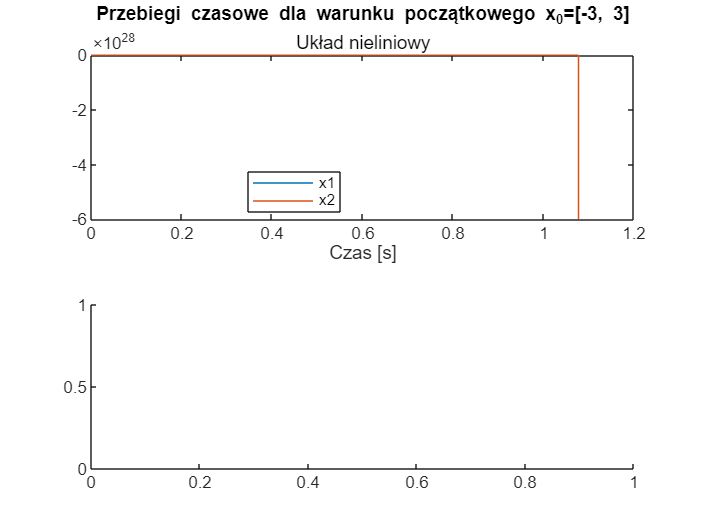

figure 
close all;
clear all;
sim_time = 20;
subplot(2,1,1)
b = 0.5;
c = 0.6;
d = -0.7;
x0=[-3, 3];
[t, xx] = ode45(@(t,x) system31(t,x,b,c,d), [0 sim_time], x0);
plot(t,xx)
title(sprintf('Przebiegi czasowe dla warunku początkowego x_0=[%g, %g]', x0(1), x0(2)))
subtitle('Układ nieliniowy')
xlabel("Czas [s]")
legend("x1","x2","Location","best")

subplot(2,1,2)

x=[0,0];
A=[0, 1; -3*d*x(1)^2-c, -b];

Unrecognized function or variable 'x'.

[t1, xx1] = ode45(@(t,x) A*[x(1);x(2)], [0 sim_time], x0);
plot(t1,xx1)
subtitle('Układ zlinearyzowany')
xlabel("Czas [s]")
legend("x1","x2","Location","best")
%saveas(gcf,'przebiegi13.png')

figure 
close all;
clear all;
sim_time = 20;
subplot(2,1,1)
b = 0.5;
c = 0.6;
d = -0.7;
x0=[0, 4];
[t, xx] = ode45(@(t,x) system31(t,x,b,c,d), [0 sim_time], x0);
plot(t,xx)
title(sprintf('Przebiegi czasowe dla warunku początkowego x_0=[%g, %g]', x0(1), x0(2)))
subtitle('Układ nieliniowy')
xlabel("Czas [s]")
legend("x1","x2","Location","best")

subplot(2,1,2)
x=[0,0];
A=[0, 1; -3*d*x(1)^2-c, -b];
[t1, xx1] = ode45(@(t,x) A*[x(1);x(2)], [0 sim_time], x0);
plot(t1,xx1)
subtitle('Układ zlinearyzowany')
xlabel("Czas [s]")
legend("x1","x2","Location","best")
%saveas(gcf,'przebiegi14.png')

## Wahadło


$$\ddot{y}(t) + \frac{g}{l}\sin{y}(t) + \frac{c}{lm}\dot{y}(t) = 0$$


clear all
syms c l m g x1 x2
J = [0 1; -g/l*cos(x1) -c/l*m]

% P(2kpi, 0)
J1 = [0 1; -g/l -c/(l*m)]
eig(J1)

% P((2k+1)pi, 0)
J2 = [0 1; g/l -c/(l*m)]
eig(J2)

clear all
g = 9.81;
c = 2.5;
m = 5;
l = 5;

x0 = [-pi 2.4]; %jeden pełny obrót
x02 = [-pi 3]; %dwa pełne obroty
[t,x] = ode45(@(t,x) system38(t, x, c, l, m), [0 100], x0);
[t2,x2] = ode45(@(t,x) system38(t, x, c, l, m), [0 100], x02);

odefun = @(t, x)system38(t, x, c, l, m);
plotpp(odefun, 'xlim', [-5, 15], 'ylim', [-5, 5])
hold on
x_ = [];
y_ = [];

for x_1 = -15:0.1:15
    for x_2 = -15:0.1:15
        [t,y] = ode45 (@(t, x)system38(t, x, c, l, m), [0 100], [x_1 x_2] );
        if abs(y(end,1)) < 0.1 && abs(y(end, 2)) < 0.1 
            x_(end + 1) = x_1;
            y_(end + 1)= x_2;
        end
    end
end

arg = [];
first = [];
second = [];
for x_1 = x_
    arg(end + 1) = x_1;
    index = find(x_ == x_1);
    values = y_(index);
    first(end + 1) = min(values);
    second(end + 1) = max(values);
end

x_ = [arg,sort(arg, 'descend')];
y_ = [first, flip(second)];
p = fill (x_ ,y_ ,[0.3010 0.7450 0.9330],'FaceAlpha',0.3);
p.EdgeColor = [0.3010 0.7450 0.9330];
plot(0, 0, '.', 'Color', 'red')
plot(-2* pi, 0, '.', 'Color', 'red')
plot(2* pi, 0, '.', 'Color', 'red')
plot(3* pi, 0, '.', 'Color', 'red')
plot(x(:, 1), x(:, 2), 'r-')
plot(x2(:, 1), x2(:, 2), 'g-')
hold off

x0 = [0.1 0.1];
J = [0 1; -g/l -c/(l*m)];
plotpp(@(t, x)J*[x(1); x(2)])
J = [0 1; g/l -c/(l*m)];
plotpp(@(t, x)J*[x(1); x(2)])

## Układ Van der Pola


$$\dot{x_{1}} = x_{2} - x_{1}^3 - ax_{1}$$



$$\dot{x_{2}} = -x_{1}$$


clear all
syms x1 x2

a = -3;

J = [-3*x1^2-1 1; -1 0]
% P(0,0)
J1 = [-1 1; -1 0]
eig(J1)

odefun = @(t, x)system39(t, x, a);
plotpp(odefun)
hold on
plot(0, 0, '.', 'Color', 'red')
hold off

x0 = [0.1 0.1];
J1 = [3 1; -1 0]
plotpp(@(t, x)J1*[x(1); x(2)])

figure 
close all;
clear all;
sim_time = 10;
subplot(2,1,1)
a = -3;
x0=[5, 5];
[t, xx] = ode45(@(t,x) system39(t,x,a), [0 sim_time], x0);
plot(t,xx)
title(sprintf('Przebiegi czasowe dla warunku początkowego x_0=[%g, %g]', x0(1), x0(2)))
subtitle('Układ nieliniowy')
xlabel("Czas [s]")
legend("x1","x2","Location","best")

subplot(2,1,2)
x=[0,0];
A=[-a, 1; -1, 0];
T=6;
[t1, xx1] = ode45(@(t,x) A*[x(1);x(2)], [0 sim_time], x0);
plot(t1,xx1)
subtitle('Układ zlinearyzowany')
xlabel("Czas [s]")
legend("x1","x2","Location","best")
%saveas(gcf, 'przebiegi21.png')

figure 
close all;
clear all;
sim_time = 10;
subplot(2,1,1)
a = -3;
x0=[0, 3];
[t, xx] = ode45(@(t,x) system39(t,x,a), [0 sim_time], x0);
plot(t,xx)
title(sprintf('Przebiegi czasowe dla warunku początkowego x_0=[%g, %g]', x0(1), x0(2)))
subtitle('Układ nieliniowy')
xlabel("Czas [s]")
legend("x1","x2","Location","best")

subplot(2,1,2)
x=[0,0];
A=[-a, 1; -1, 0];
T=6;
[t1, xx1] = ode45(@(t,x) A*[x(1);x(2)], [0 sim_time], x0);
plot(t1,xx1)
subtitle('Układ zlinearyzowany')
xlabel("Czas [s]")
legend("x1","x2","Location","best")
%saveas(gcf,'przebiegi22.png')

function dxdt = system31(t, x, b, c, d)
    dxdt = zeros(2, 1);
    dxdt(1) = x(2);
    dxdt(2) = -c*x(1) - d*x(1)^3 - b*x(2);
end %system31


function dxdt = system38(t, x, c, l, m)
    dxdt = zeros(2, 1);
    dxdt(1) = x(2);
    dxdt(2) = -9.81/l * sin(x(1)) - c/(l*m) * x(2);
end %system38


function dxdt = system39(t, x, a)
    dxdt = zeros(2, 1);
    dxdt(1) = x(2) - x(1)^3 - a*x(1);
    dxdt(2) = -x(1);
end %system39